# META 2

## 11

%% Meta 2: Cálculo dos Coeficientes da Série Complexa de Fourier
% Carrega a estrutura de dados previamente salva (arquivo AED1.mat)
load('AED1.mat');  % A variável 'tab' deve estar presente

% Verifica se o campo 'Sinal_Processado' existe na tabela
if ~ismember('Sinal_Processado', tab.Properties.VariableNames)
    error('O campo "Sinal_Processado" não existe na tabela.');
end

% Número de arquivos/sinais
nArquivos = height(tab);

% Calcula os coeficientes de Fourier para cada sinal processado e armazena na mesma tabela
for i = 1:nArquivos
    s = tab.Sinal_Processado{i};  % Recupera o sinal processado
    tab.FourierCoeffs{i} = fft(s);  % Calcula e armazena os coeficientes
end

% Salva a tabela atualizada (mantendo a mesma estrutura de dados)
save('AED1.mat', 'tab');
disp(tab);

## 12

%% Cálculo e Visualização do Espectro de Amplitude Mediano e Quartis com Frequências até 8000 Hz
% Considera que 'tab' já contém os campos: Sinal_Processado, Digito e Taxa_Amostragem


                        Diretorio_Audio                         Nome_Arquivo      Digito    Participante    Repeticao    Sinal_Processado    Taxa_Amostragem    EnergiaTotal    EnergiaPrimeiraMetade    EnergiaSegundaMetade    DesvioPadraoAmplitude      RMS      MediaAmplitude    FatorCrest    TaxaCruzamento     FourierCoeffs  
    _______________________________________________________    _______________    ______    ____________    _________    ________________    _______________    ____________    _____________________    ____________________    

% Identifica os dígitos únicos
digitosUnicos = unique(tab.Digito);
numDigitos = numel(digitosUnicos);

% Cria uma figura maior (tela cheia)
figure('Name', 'Espectro de Amplitude Mediano e Quartis por Dígito', ...
       'Units','normalized','OuterPosition',[0 0 1 1]);

% Para armazenar os handles das linhas do primeiro subplot (para a legenda comum)
hMed = []; hQ1 = []; hQ3 = [];

% Loop sobre cada dígito
for k = 1:numDigitos
    digitoAtual = digitosUnicos(k);
    idx = find(tab.Digito == digitoAtual);
    numSinais = numel(idx);
    
    % Usa o primeiro sinal para obter a taxa de amostragem e o tamanho do sinal
    s_exemplo = tab.Sinal_Processado{idx(1)};
    fs = tab.Taxa_Amostragem(idx(1));
    N = length(s_exemplo);
    
    % Define os índices para frequências positivas (inclui DC e termo de Nyquist se aplicável)
    posIdx = 1:floor(N/2)+1;
    
    % Calcula o vetor de frequências (em Hz)
    f = (posIdx - 1) * fs / N;
    
    % Seleciona apenas as frequências até 8000 Hz
    cutoffIdx = find(f <= 8000);
    f = f(cutoffIdx);
    
    % Inicializa a matriz para armazenar os espectros de amplitude
    espectros = zeros(length(cutoffIdx), numSinais);
    for j = 1:numSinais
        s = tab.Sinal_Processado{idx(j)};
        fftS = fft(s) / N;                % FFT normalizada pelo número de amostras
        espectro = abs(fftS(posIdx));       % Módulo para frequências positivas
        espectros(:, j) = espectro(cutoffIdx);
    end
    
    % Calcula para cada frequência a mediana, o 1º quartil (25%) e o 3º quartil (75%)
    mediano = median(espectros, 2);
    q1 = quantile(espectros, 0.25, 2);
    q3 = quantile(espectros, 0.75, 2);
    
    % Cria o subplot para o dígito atual
    subplot(ceil(numDigitos / 2), 2, k);
    h1 = plot(f, mediano, 'b-', 'LineWidth', 2); hold on;
    h2 = plot(f, q1, 'r-', 'LineWidth', 1.5);
    h3 = plot(f, q3, 'Color',[0.929, 0.694, 0.125], 'LineWidth', 1.5); % amarelo/dourado
    hold off;
    
    xlabel('Frequência (Hz)');
    ylabel('Amplitude');
    title(sprintf('Dígito %d', digitoAtual));
    grid on;
    
    % Armazena os handles do primeiro subplot para criar uma legenda comum
    if k == 1
        hMed = h1;
        hQ1 = h2;
        hQ3 = h3;
    end
end

% Cria uma legenda comum para todos os subplots (posição ajustada conforme necessário)
legend([hMed, hQ1, hQ3], {'Mediana','1º Quartil (25%)','3º Quartil (75%)'}, ...
       'Orientation','horizontal','Position',[0.35 0.95 0.3 0.03]);

sgtitle('Espectro de Amplitude Mediano e Quartis para Cada Dígito (até 8000 Hz)');

## 13

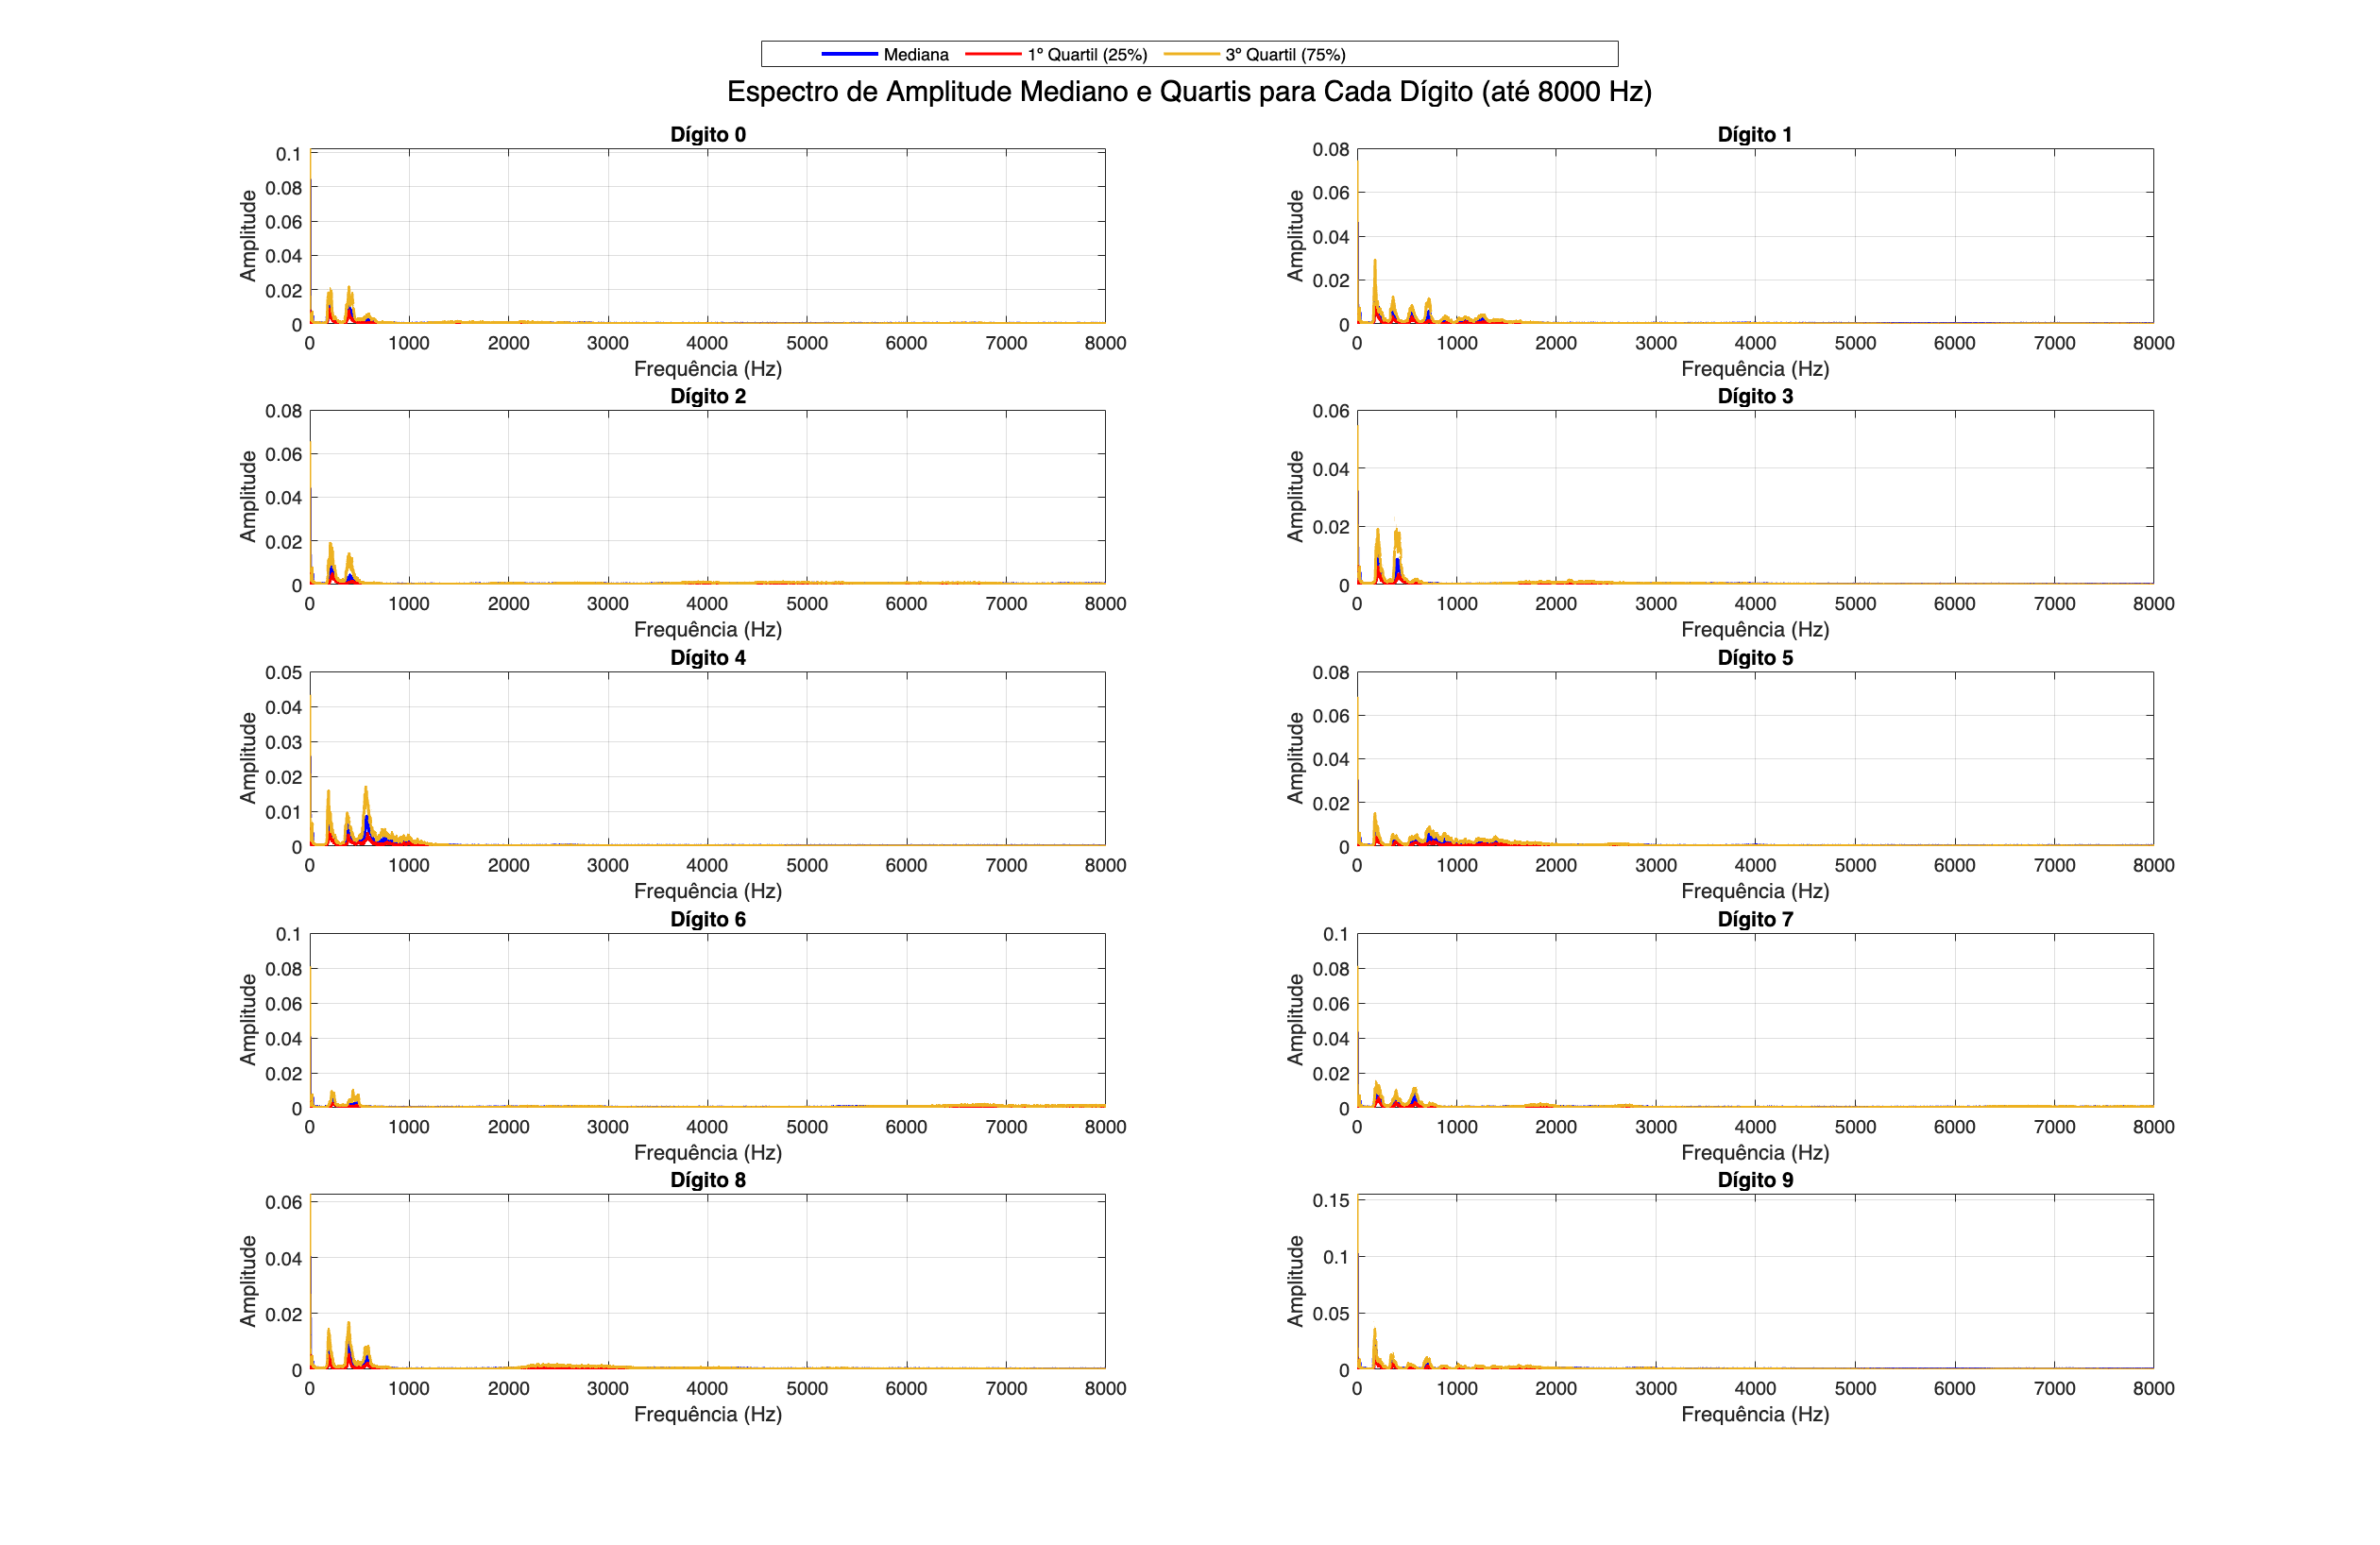

%% Cálculo de Características Espectrais para Diferenciação entre Dígitos
% Assume que 'tab' já contém os campos 'Sinal_Processado' e 'Taxa_Amostragem'

% Número de arquivos (linhas da tabela)
nArquivos = height(tab);


% Inicializa os vetores coluna para armazenar as características espectrais
maxSpectralAmplitude     = zeros(nArquivos,1);

Unable to perform assignment because the left and right sides have a different number of elements.

freqMaxSpectralAmplitude = zeros(nArquivos,1);
spectralMean             = zeros(nArquivos,1);
spectralEdgeFrequency    = zeros(nArquivos,1);
spectralBandwidth        = zeros(nArquivos,1);

% Percentual para o cálculo da spectral edge frequency (exemplo: 90% da energia)
edgePercent = 0.90;

for i = 1:nArquivos
    s = tab.Sinal_Processado{i};
    fs = tab.Taxa_Amostragem(i);
    N = length(s);
    
    % Calcula a FFT normalizada
    fftS = fft(s) / N;
    
    % Considere apenas as frequências positivas
    posIdx = 1:floor(N/2)+1;
    fftS_pos = fftS(posIdx);
    
    % Vetor de frequências (em Hz)
    f = (posIdx - 1) * fs / N;
    
    % Magnitude do espectro
    magSpec = abs(fftS_pos);
    
    % 1. Máximo espectral (amplitude) e sua posição (frequência)
    [maxAmp, idxMax] = max(magSpec);
    maxSpectralAmplitude(i)     = maxAmp;
    freqMaxSpectralAmplitude(i) = f(idxMax);
    
    % 2. Média espectral (centroide)
    spectralMean(i) = sum(f .* magSpec) / sum(magSpec);
    
    % 3. Spectral Edge Frequency: frequência abaixo da qual se acumula 90% da energia
    powerSpec = magSpec.^2;
    totalPower = sum(powerSpec);
    cumulativePower = cumsum(powerSpec);
    idxEdge = find(cumulativePower >= edgePercent * totalPower, 1, 'first');
    if isempty(idxEdge)
        spectralEdgeFrequency(i) = f(end);
    else
        spectralEdgeFrequency(i) = f(idxEdge);
    end
    
    % 4. Spectral Bandwidth: desvio padrão das frequências ponderado pela magnitude
    spectralBandwidth(i) = sqrt(sum(((f - spectralMean(i)).^2) .* magSpec) / sum(magSpec));
end

% 5. Como quinta característica, calculamos a energia total do espectro
spectralEnergy = zeros(nArquivos,1);
for i = 1:nArquivos
    s = tab.Sinal_Processado{i};
    fs = tab.Taxa_Amostragem(i);
    N = length(s);
    fftS = fft(s) / N;
    posIdx = 1:floor(N/2)+1;
    magSpec = abs(fftS(posIdx));
    spectralEnergy(i) = sum(magSpec.^2);
end

% Caso a tabela já possua alguma coluna com estes nomes, pode-se sobrescrevê-las sem problemas.
% Para garantir que as dimensões estão corretas, forçamos a conversão para vetor coluna:
tab.MaxSpectralAmplitude     = maxSpectralAmplitude(:);
tab.FreqMaxSpectralAmplitude = freqMaxSpectralAmplitude(:);
tab.SpectralMean             = spectralMean(:);
tab.SpectralEdgeFrequency    = spectralEdgeFrequency(:);
tab.SpectralBandwidth        = spectralBandwidth(:);
tab.SpectralEnergy           = spectralEnergy(:);

% Exibe a tabela atualizada e salva
disp(tab);
save('AED1.mat', 'tab');

